% cobot fpga+注释ethercat状态机
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC.csv';
data = readtable(filename);

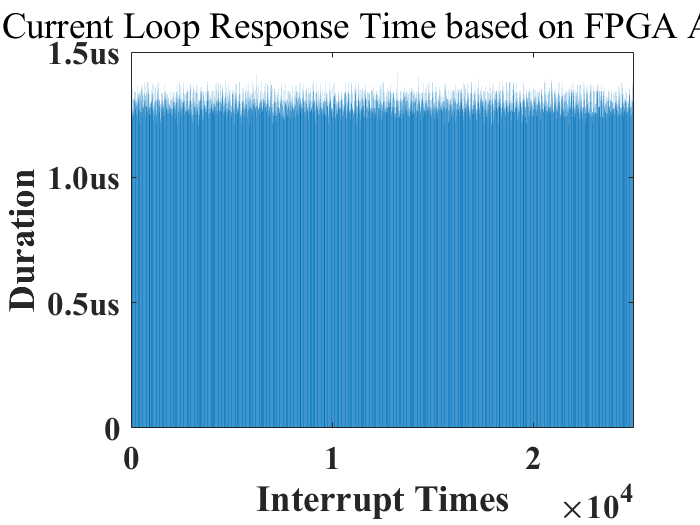

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time based on FPGA ADC');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 1.2993e-06

% cobot h743+注释ethercat状态机
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_H743ADC.csv';
data = readtable(filename);

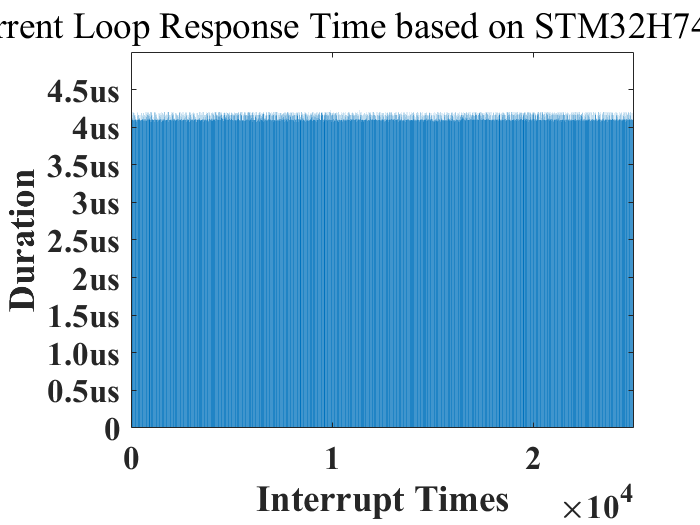

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time based on STM32H743 ADC');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 4.1354e-06

% cobot FPGA+注释ethercat状态机+注释电流环
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC_withoutCurrentLoop.csv';
data = readtable(filename);

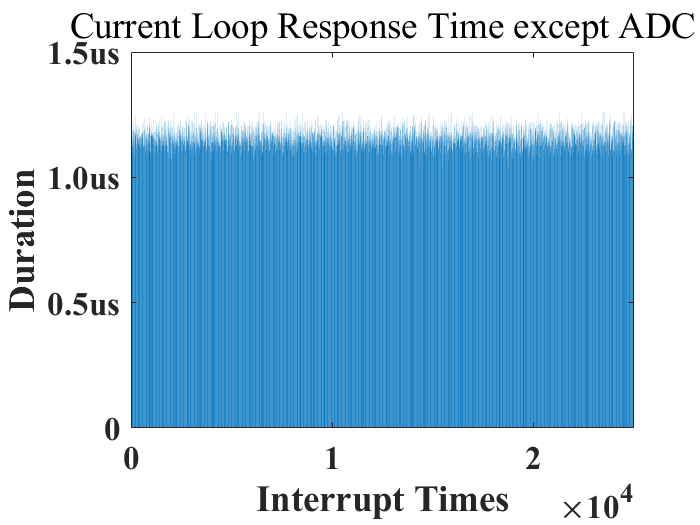

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time except ADC');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 1.1627e-06

% cobot FPGA+注释ethercat状态机+注释编码器
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC_withoutEncoder.csv';
data = readtable(filename);

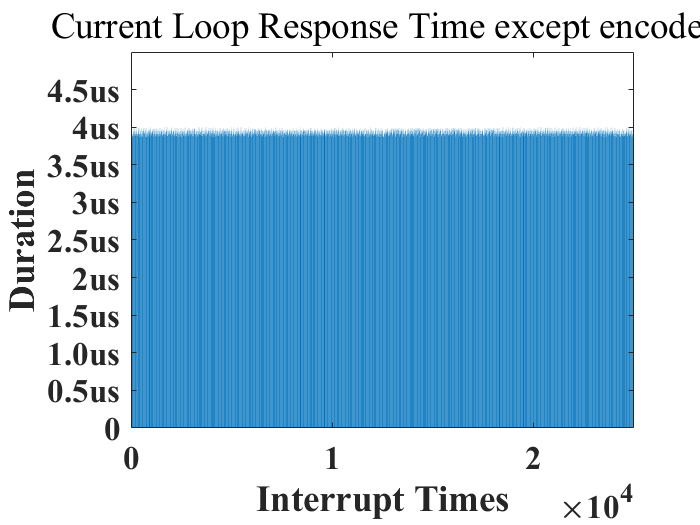

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time except encoder');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 3.9298e-06

% cobot FPGA+注释ethercat状态机+注释foc
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC_withoutFOC.csv';
data = readtable(filename);

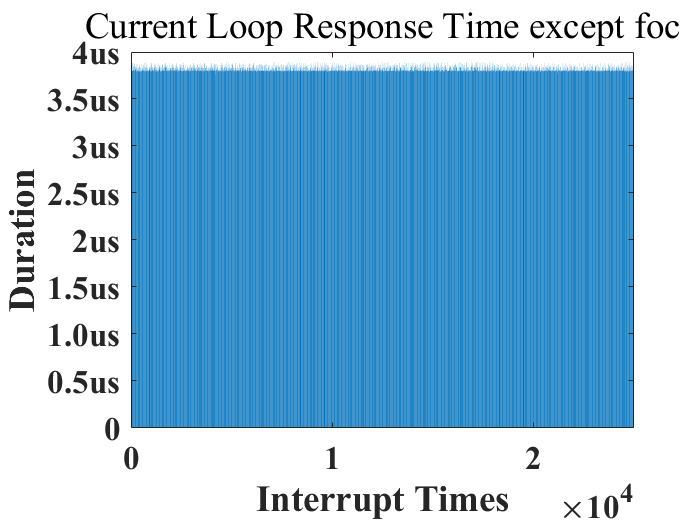

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time except foc');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 3.8192e-06

% cobot FPGA+注释ethercat状态机+注释ethercat
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC_withoutEtherCAT.csv';
data = readtable(filename);

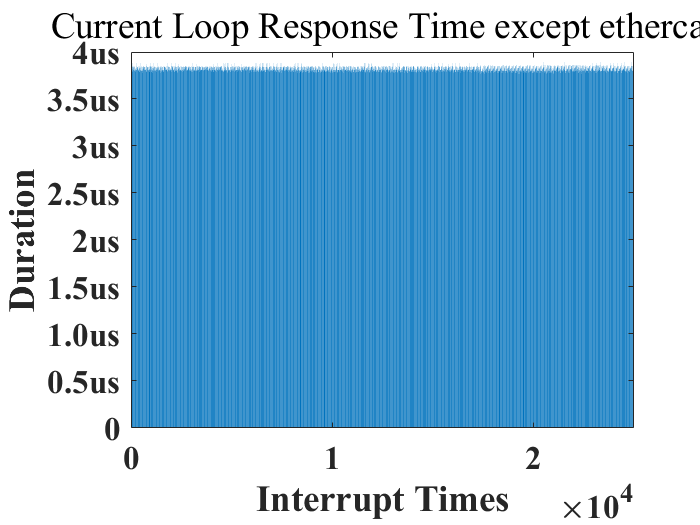

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time except ethercat');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 3.8220e-06

% cobot FPGA+注释ethercat状态机+注释operation state
filename = 'G:\ad_file\servo2022hardware\test\test_torque_time\CurrentLoopResponseTime_FPGAADC_withoutOperationStateMachine.csv';
data = readtable(filename);

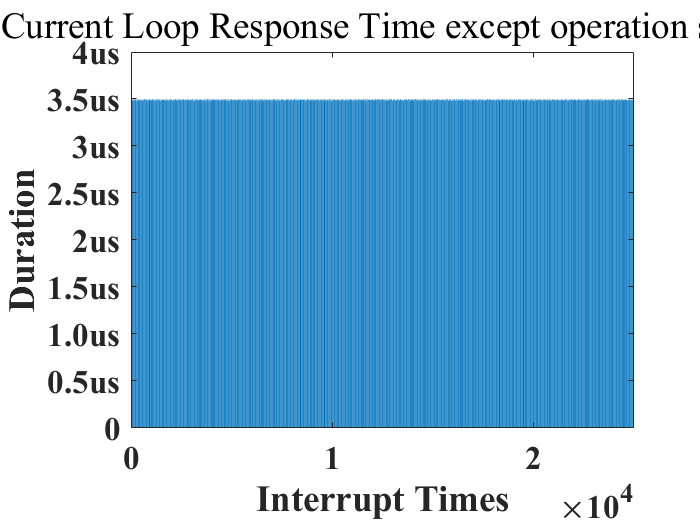

time = table2array(data(:,1));
value = table2array(data(:,2));
%plot(time,value);
len_data=length(time);
t_torque=[];
for i=1:len_data
        if value(i,1)==1
        t_torque=[t_torque,time(i+1)-time(i)];
        end
end

threshold = 0.5e-6;
indices_to_remove = t_torque < threshold;
t_torque(indices_to_remove) = [];

bar(t_torque);
xlabel('Interrupt Times');  % 添加x轴标签
ylabel('Duration');  % 添加y轴标签
title('Current Loop Response Time except operation state');  % 添加图标题
yticks([0:0.5:4.5]*10^-6);
yticklabels({'0','0.5us','1.0us','1.5us','2us','2.5us','3us','3.5us','4us','4.5us','5us'});
set(gca, 'FontName', 'Times New Roman');  % 设置字体为
set(gca, 'FontWeight', 'bold');
set(gca, 'FontSize', 20);


currentLoopResponseTime_average=mean(t_torque(:))

currentLoopResponseTime_average = 3.4920e-06